# Getting started with the Computational Physiology Toolbox

The Computational Physiology Toolbox provides an easy-to-use scripting interface to define and execute physiology-based modelling workflows.

### Example usage

Below is a simple script to define and run a PBPK model simulation. More complex simulation scripts can found in the `examples` folder.

Define physiology, dosing, sampling, model

obs = PBPKobservables();
indv = Individual('Virtual');
indv.physiology = Physiology('human35m');
indv.dosing = Oral('Warfarin',(0:7)*u.day, 250*u.mg);
indv.drugdata = DrugData('Warfarin','species','human');
indv.sampling = Sampling(2*u.day:30*u.min:8*u.day, obs);
indv.model = sMD_PBPK_12CMT_wellstirred;
indv.model.options.tissuePartitioning = @rodgersrowland;

Next, initialize, simulate, plot:

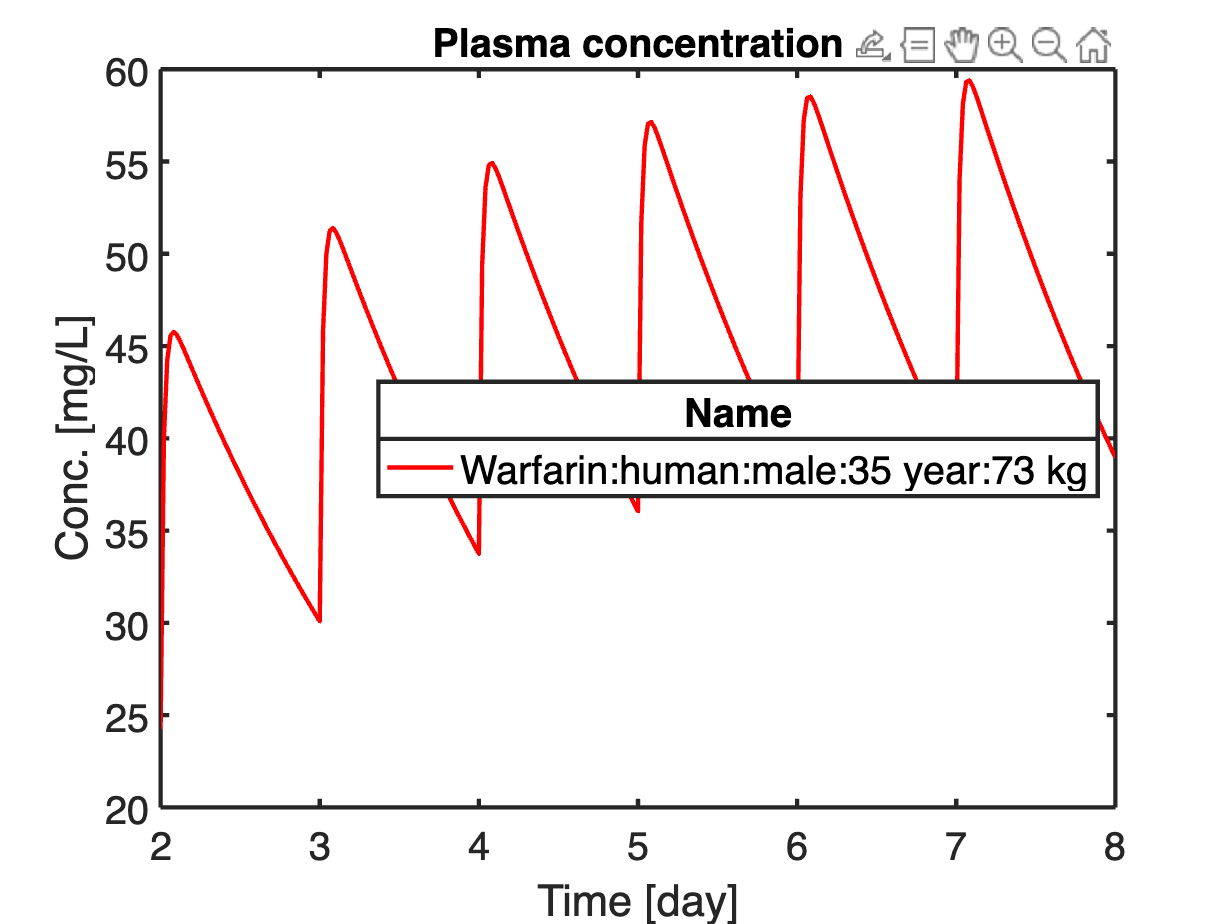

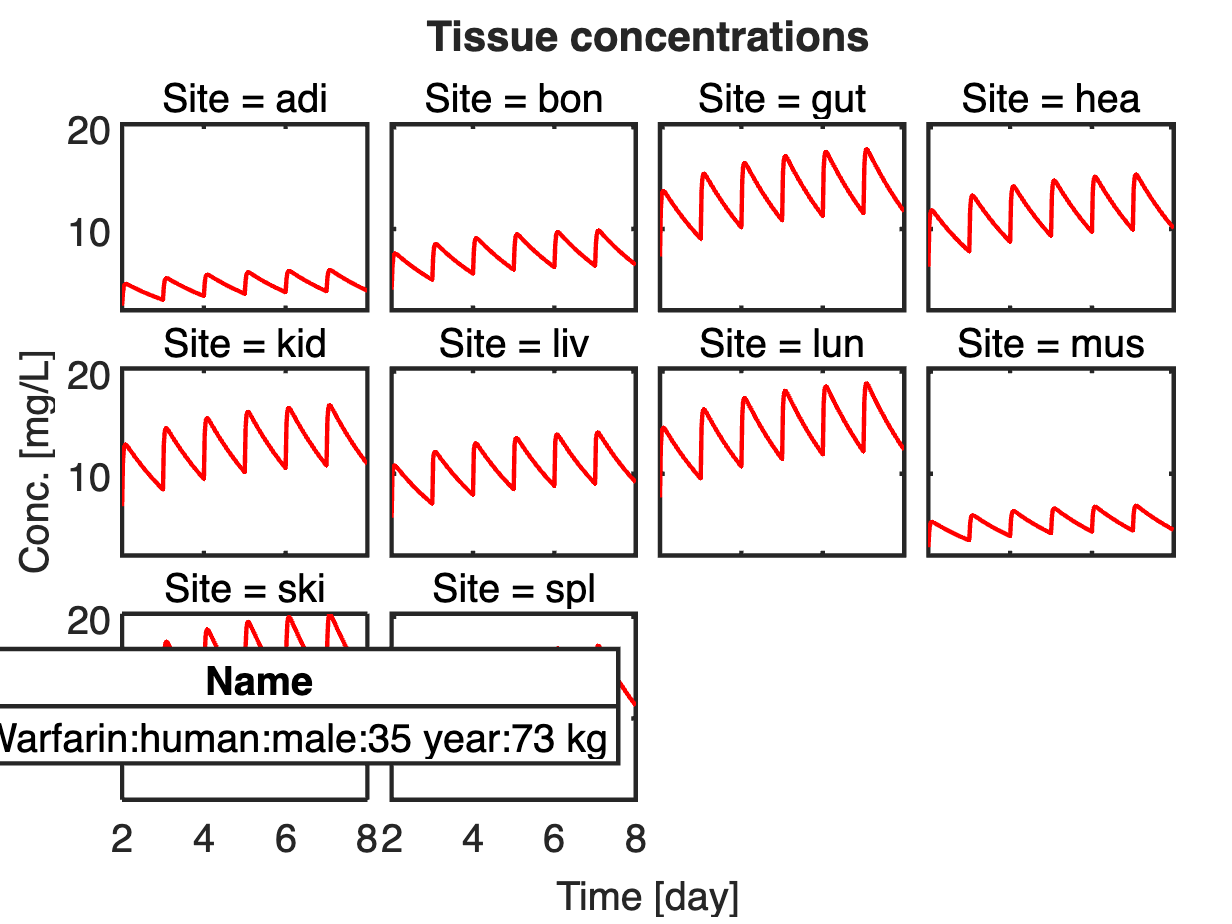

initialize(indv)
simulate(indv)
plot(indv, 'yunit', 'mg/L')